% Example on CMU Mocap dataset
% Data obtained from: http://mocap.cs.cmu.edu/

## Load data

load data/ex8_movies.mat
Xtrue = Y;
clear Y;
[n,s] = size(Xtrue);
disp(n)

        1682



disp(s)

   943



disp('job done')

job done


## Verify data is low-rank in lifted domain

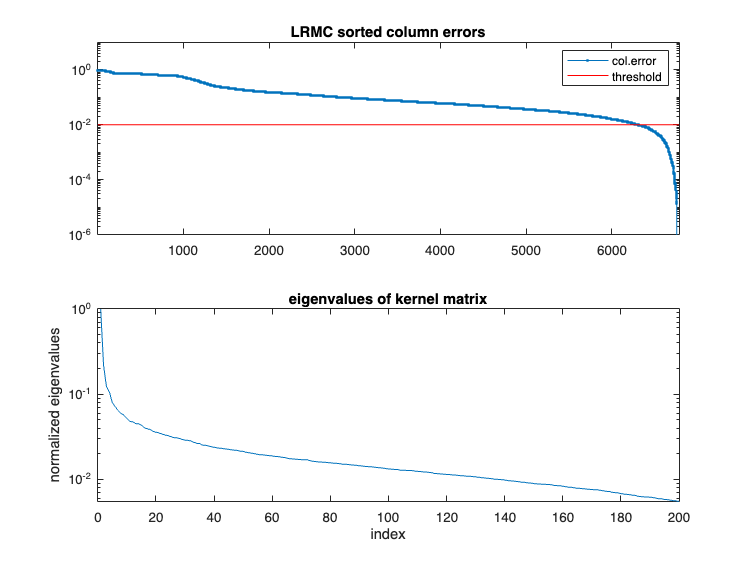

K = (Xtrue'*Xtrue).^2;
[V,S] = rsvdpsd(K,500,3,2);
figure(1);
ev = sort(diag(S),'descend');
semilogy(ev/ev(1)); title('eigenvalues of kernel matrix'); ylabel('normalized eigenvalues'); xlabel('index');

disp('job done, yay')

job done, yay


## Subsample data uniformly at random

rng(10); %fix random seedf
missrate = 0.1;
rind = randperm(n*s);
rv = round((1-missrate)*n*s);
sampmask = false(n,s);
sampmask(rind(1:rv)) = true;

samples = Xtrue(sampmask);
Xinit = zeros(n,s);
Xinit(sampmask) = samples;
disp('job done')

job done


## Run low-rank matrix completion (LRMC)

options_nn.lambda = 1e8;
options_nn.mu = 1;
options_nn.niter = 500;
Xlrmc = lrmc_admm(Xinit,sampmask,samples,options_nn);
fprintf('LRMC NRMSE = %1.2e\n',norm(Xlrmc-Xtrue,'fro')/norm(Xtrue,'fro'));
disp('job done')

## Run variety-based matrix completion (VMC)

options = [];
options.d = 2; %kernel degree
options.niter = 300;
options.eigcomp = 'kernel-rsvd';
options.rmax = 200;
options.eigtol = 1e-7; %keep small for stable convergence
options.gamma0 = 1;

% warning: takes ~30 minutes to run on a Macbook Pro 3.1 GHz Intel Core i7
% reduce number of iterations for faster runtime
tic;
[Xvmc,cost,update,error] = vmc(Xinit,sampmask,samples,options,Xtrue);
toc;

Elapsed time is 50.390017 seconds.



fprintf('VMC NRMSE = %1.2e\n',norm(Xvmc-Xtrue,'fro')/norm(Xtrue,'fro'));

VMC NRMSE = 2.71e-01


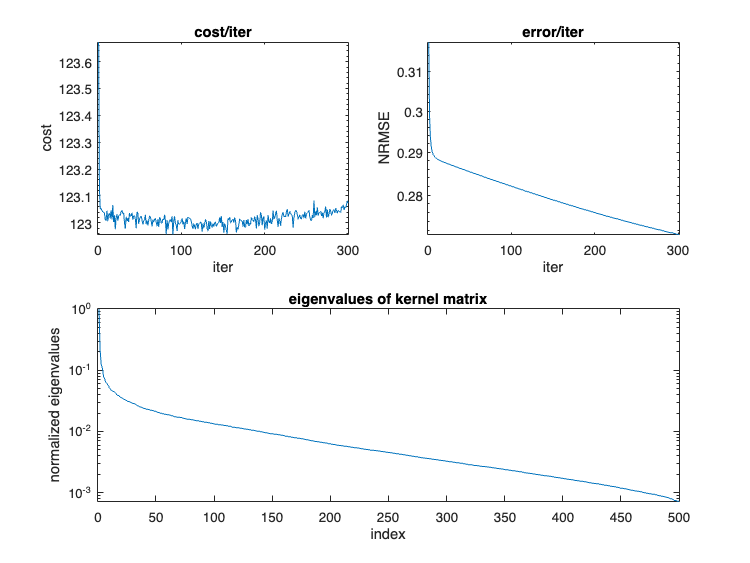


figure(1);
subplot(2,2,1);
semilogy(cost); title('cost/iter'); ylabel('cost'); xlabel('iter');
subplot(2,2,2);
semilogy(error); title('error/iter'); ylabel('NRMSE'); xlabel('iter');

subplot(2,2,3);
semilogy(update); title('update/iter'); ylabel('NRMSE'); xlabel('iter');
disp('job done')

job done


## Display columnwise errors

figure(2);
colerr_vmc = zeros(1,s);
colerr_lrmc = zeros(1,s);
for j = 1:s
    colerr_vmc(j) = norm(Xvmc(:,j)-Xtrue(:,j))/norm(Xtrue(:,j));
    colerr_lrmc(j) = norm(Xlrmc(:,j)-Xtrue(:,j))/norm(Xtrue(:,j));
end

Arrays have incompatible sizes for this operation.

Related documentation

[colerr_vmc,idx] = sort(colerr_vmc,'descend');
[colerr_lrmc,idx] = sort(colerr_lrmc,'descend');
errthresh = 1e-2;

subplot(2,1,1);
semilogy(colerr_lrmc,'.-'); title('LRMC sorted column errors');
hold on
line([0 s],[errthresh errthresh],'Color','red');
hold off
axis([1 s 1e-6 10]);
legend('col.error','threshold');
subplot(2,1,2);
semilogy(colerr_vmc,'.-'); title('VMC sorted column errors');
hold on
line([0 s],[errthresh errthresh],'Color','red');
hold off
legend('col.error','threshold');
axis([1 s 1e-6 10]);
fprintf('LRMC recovered %2.1f%% columns (%d of %d) with err < %1.1e\n',(nnz(colerr_lrmc < errthresh)/s)*100,nnz(colerr_lrmc < errthresh),s,errthresh);
fprintf('VMC recovered %2.1f%% columns (%d of %d) with err < %1.1e\n',(nnz(colerr_vmc < errthresh)/s)*100,nnz(colerr_vmc < errthresh),s,errthresh);
disp('job done')